# 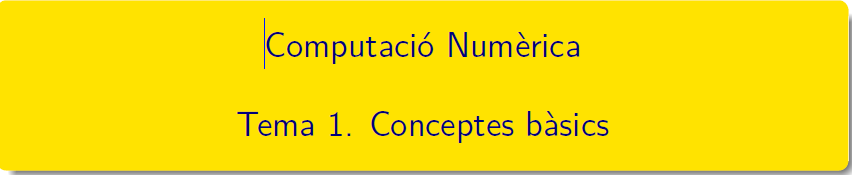

=======================================================================================

# Tema 1 - Conceptes Bàsics

## 1. Introducció a MATLAB

El document del campus, Instalar_MATLAB_Campus_Estudiantes_UPC.pdf explica com obtenir aquest software per a tot l'alumnat de la UPC.

[ Cleve’s Corner: Cleve Moler on Mathematics and Computing](https://blogs.mathworks.com/cleve/)

[A Brief History of MATLAB](https://es.mathworks.com/company/newsletters/articles/a-brief-history-of-matlab.html?s_tid=srchtitle)

## 2. Anàlisis de l'error

### Error absolut i error relatiu.

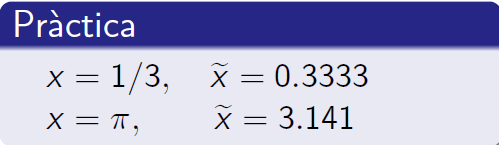

format short
x = 1/3, xa = 0.3333

x = 0.3333

xa = 0.3333

% error('no puc fer us de la funcio')
ea = abs(x-xa), er = ea /abs(xa), erp = er*100

ea = 3.3333e-05

er = 1.0001e-04

erp = 0.0100

format short
x = pi, xa = 3.141

x = 3.1416

xa = 3.1410

ea = abs(x-xa), er = ea /abs(xa), erp = er*100

ea = 5.9265e-04

er = 1.8868e-04

erp = 0.0189

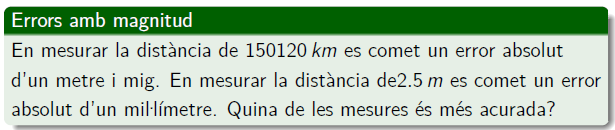

x = 150120*1000; % (en metres)
ea = 1.5; erp = ea/abs(x)*100

erp = 9.9920e-07

x = 2.5*1000; % (en mm)
ea = 1; erp = ea/abs(x)*100

erp = 0.0400

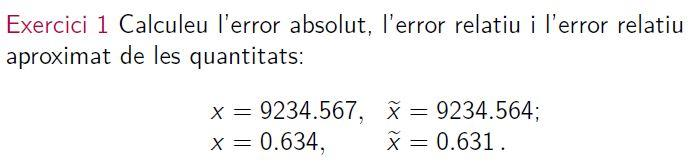

format short g
% a)
x = 9234.567; xa =9234.564;
ea = abs(x-xa), er = ea/abs(x)

ea =         0.003


er =    3.2487e-07


% b)
x = 0.634; xa =0.631;
ea = abs(x-xa), er = ea/abs(x)

ea =         0.003


er =     0.0047319


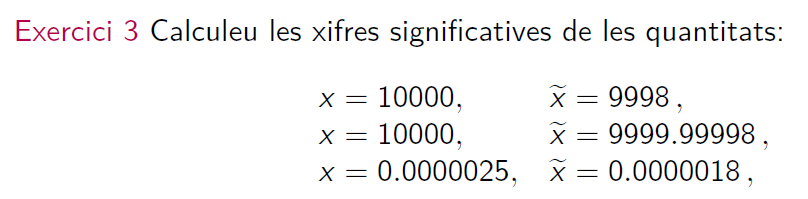

% a)
x = 10000; xa = 9998;
ea = abs(x-xa), er = ea/abs(x)

ea =      2


er =        0.0002


% b)
x = 10000; xa = 9999.99998;
ea = abs(x-xa), er = ea/abs(x)

ea =         2e-05


er =         2e-09


% c)
x = 25/10^7; xa =18/10^7;
ea = abs(x-xa), er = ea/abs(x)

ea =         7e-07


er =          0.28


### **Errors d'arrodoniment (representació de nombres)**

El 2/3 es pot representar per 0.66666 truncant l'expressió decimal o per 0.66667 arrodonint l'expressió decimal, en aquest cas l'error d'arrodoniment és:

format longG
x = 2/3;
xt = fix(x*10^5)/10^5
% ear = abs(x-xt)
xa = round(x,5)
% ear = abs(x-xa)

### **Errors de truncament (document apart)**

### **Errors de discretització (document apart)**

### Propagació de l'error 

Exercicis Full_ExercicisTema1.pdf

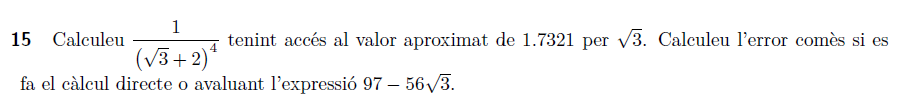

Cálcul del valor

format shortG
x = sqrt(3); xa = 1.7321; f = 1/(x+2)^4; fa = 1/(xa+2)^4; 
g = 97-56*x; ga = 97-56*xa;

Anàlisi de l'error

ea = abs(x-xa), eaf = abs(f-fa)

ea =    4.9192e-05


eaf =    2.7177e-07


 eag = abs(g-ga)    % Al fer 56*^sqrt(3) fa que amplifiqui l'error

eag =     0.0027548


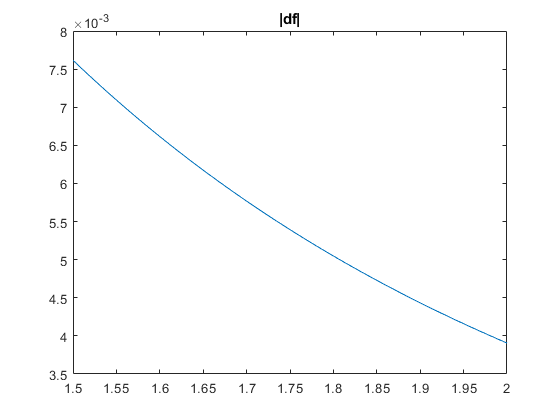

 x = linspace(1.5,2);
 df = 4./(x+2).^5;
 plot(x,df),title('|df|')

## 3. Algorismes

### Algorismes amb cancel·lació

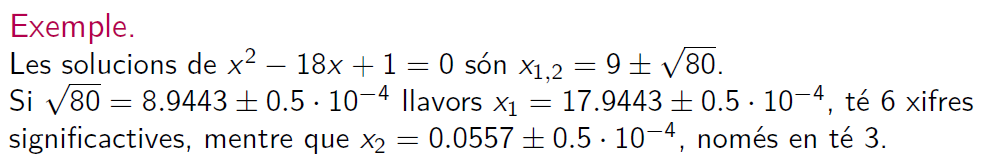

format shortG
format compact
a80 = 8.9443;
x1 = 9+a80, x = 9+sqrt(80), 

x1 =        17.944

x =        17.944

y1 = 9-a80, y = 9-sqrt(80),     % He perdut informació

y1 =        0.0557

y =      0.055728

z1 = 1/x1, z = 1/x              % No he perdut informació

z1 =      0.055728

z =      0.055728

### Estabilitat numèrica 

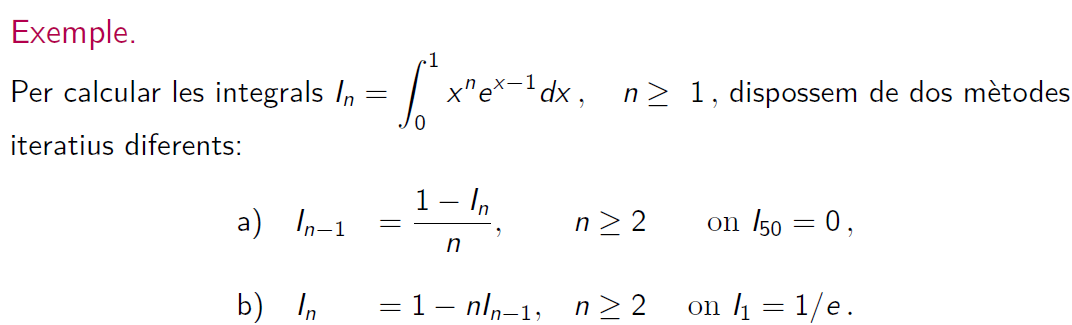

### Sensibles a les condicions inicials (I)

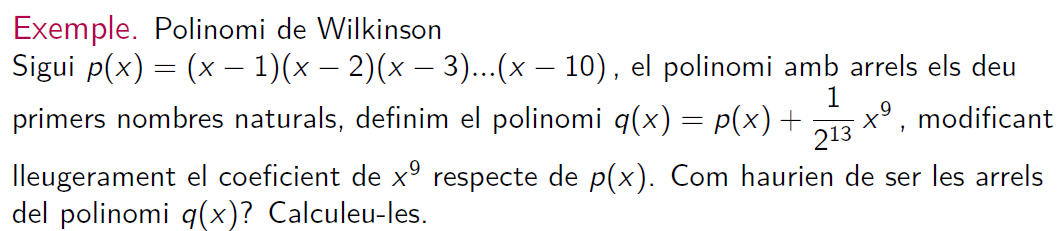

clearvars
format shortG
r = 1:10;
p = poly(r); arrels = roots(p);
q = p; q(2) = q(2)+1/2^(13); format longG, [p;q]'
roots (q)   % no se recuperen a partir del 6

### Sistema lineal mal condicionat (II)

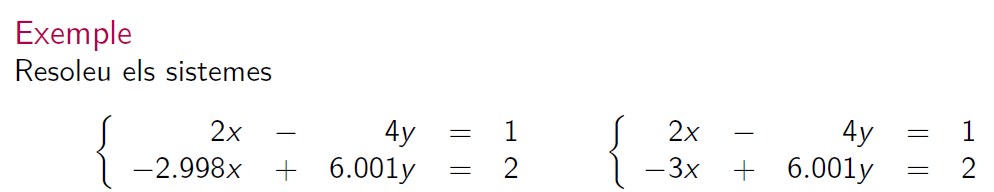

clearvars
format shortG

### Evitar la propagació d'errors

Per tal de reduir o evitar la propagació dels errors es recomana, minimitzar el nombre d’operacions, reordenar les operacions i replantejar el problema en altres termes.

#### Equació de segon grau

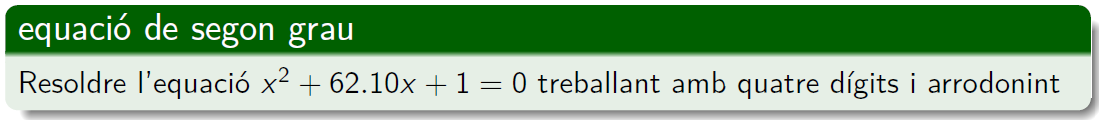

clearvars, format, n=4;

ans =                          1                         1
                       -55         -54.9998779296875
                      1320                      1320
                    -18150                    -18150
                    157773                    157773
                   -902055                   -902055
                   3416930                   3416930
                  -8409500                  -8409500
                  12753576                  12753576
                 -10628640                 -10628640


fprintf('fent ús de roots')

ans =            9.71680694440454 +     0.423492822039221i
           9.71680694440454 -     0.423492822039221i
           7.39701333900533 +     0.749263119716399i
           7.39701333900533 -     0.749263119716399i
           5.67612069756221 +                     0i
           5.10313498919566 +                     0i
           3.99274462886153 +                     0i
           3.00023859699748 +                     0i
           1.99999844991441 +                     0i
           1.00000000033645 +                     0i


Es calcula amb la fórmula $\frac{-b\pm\sqrt{b^2-4ac}}{2a}=-31.05\pm\sqrt{31.05^2-1}$

Es calcula amb la fórmula $x_1=-31.05-\sqrt{31.05^2-1},\quad  x_3 = 1/x_1$

Xifres decimales correctes

#### Regla de Horner

Per avaluar expressions polinomials 

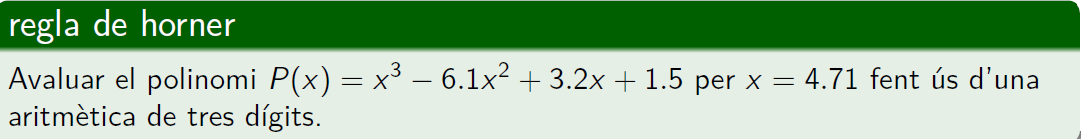

- Evaluar el polinomi $x^3 -6\ldotp 1x^2 +3\ldotp 2x+1\ldotp 5$ en $x=4\ldotp 71$

- Evaluar el polinomi $x^3 -6\ldotp 1x^2 +3\ldotp 2x+1\ldotp 5$ en $x=4\ldotp 71$fent ús d'una aritmètica aritmética de tres dígits

- Xifres significatives

function [ pa ] = horner(coeff,a)
%   HORNER avalua el polinomi de grau n
%   p(x) = coeff(1)x.^n + coeff(2)x.^(n-1) + ... + coeff(n-1)x + coeff(n)
%   en x=a pel mètode de horner
pa = coeff(1);
x=a;
for k=2:length(coeff)
    pa = pa.*x + coeff(k);
end
return
end
function [ pa ] = hornerD(coeff,a,d)
%   HORNER avalua el polinomi de grau n
%   p(x) = coeff(1)x.^n + coeff(2)x.^(n-1) + ... + coeff(n-1)x + coeff(n)
%   en x=a pel mètode de horner fent ús de d dígits
Coeff = round(coeff,d,'significant');
A = round(a,d,'significant');
pa = round(coeff(1),d,'significant');
x=A;
for k=2:length(coeff)
    pa = round(pa.*x,d,'significant') + coeff(k);
    pa = round(pa,d,'significant');
end
return
end

`Document preparat per M. Àngela Grau Gotés, 23 de febrer de 2021`